% Read file
a = 1

a = 1

odo = load("p11_odoPose.log")

odo = 	1.0e+09 *

    0.0000    0.0000         0    0.0000         0   -0.0000    1.5876
    0.0000    0.0000         0    0.0000         0   -0.0000    1.5876
    0.0000    0.0000         0    0.0000         0   -0.0000    1.5876
    0.0000    0.0000         0    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876
    0.0000    0.0000    0.0000    0.0000         0   -0.0000    1.5876


hist = odo(:,2:4)

hist =     0.0020         0    0.0181
    0.0040         0    0.0359
    0.0060         0    0.0536
    0.0080         0    0.0721
    0.0110    0.0010    0.0898
    0.0130    0.0010    0.1084
    0.0150    0.0010    0.1261
    0.0170    0.0010    0.1446
    0.0190    0.0020    0.1623
    0.0210    0.0020    0.1793


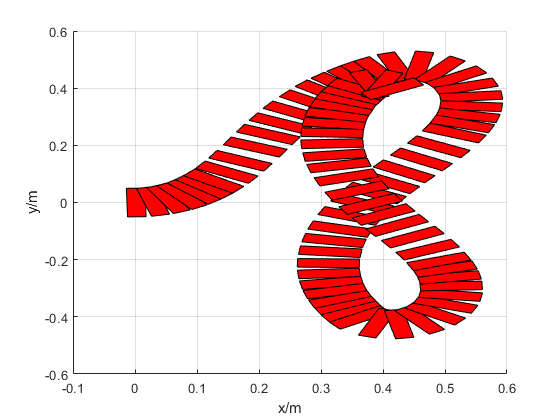

figure 
grid on
plot_hist(hist(1:1000,:), 80)
xlabel('x/m')
ylabel('y/m')

function plot_rectangle(x_coor, y_coor, angle, w, h)
    pos = [x_coor; y_coor];
    pos_1 = [-w/2;- h/2];
    pos_2 = [w/2;-h/2];
    pos_3 = [-w/2;h/2];
    pos_4 = [w/2;h/2];
    pose_1r = rot2(angle)*pos_1 + pos;
    pose_2r = rot2(angle)*pos_2 + pos;
    pose_3r = rot2(angle)*pos_3 + pos;
    pose_4r = rot2(angle)*pos_4 + pos;
    x = [pose_1r(1) pose_2r(1) pose_4r(1) pose_3r(1)];
    y = [pose_1r(2) pose_2r(2) pose_4r(2) pose_3r(2)];
    patch(x, y, 'red')
end

function plot_hist(hist, num)
    shape = size(hist);
    len = shape(1);
    step = max(5,round(len/num,0));
    if len >= 5
        for i = 1:step:len
        plot_rectangle(hist(i,1),hist(i,2),hist(i,3), 0.03,0.1)
        end
    end
end